addpath('Classes')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);

clear NL_Dcpld_EOMs

# Decouple the Equations Of Motion Starting From the Nonlinear Model

This script aids in the developement and documentation of the NL_Dcpld_EOMs class. This class decouples the system using several simplifying assumptions.

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions
end 

%Create a nonlinear decoupled EOMs object if one does not already exist. 
if (~exist('NL_Dcpld_EOMs', 'var')) 

    NL_Dcpld_EOMs = NL_Dcpld_EOMs(VDefs, BP_Kinetics); %Create an object of the class NL_Dcpld_EOMs
end



## Substitute in the Decoupling Assumptions

### x and beta Dynamics

#### Ball Kinetics

First, substitute $\gamma = \dot\gamma = 0$ into the ball's $y$ direction moment equation.

SumMBall_x = NL_Dcpld_EOMs.SumMBall_x

$$SumMBall\_x = 7\,\ddot{x}+5\,\ddot{\beta }\,z_{b}+2\,\ddot{\beta }\,r_{b}=5\,{\dot{\beta }}^{2}\,x+5\,g\,\sin\left(\beta \right)$$

#### Plate Kinetics

Next, do the kinetics of the plate alone and isolate the $y$ direction moment equation. Make the same assumptions as above and keep the moment due to the normal force, $M_N$, general for now. $M_N$ is defined with respect to the S1 frame. 

SumMPlate_x = NL_Dcpld_EOMs.SumMPlate_x

$$SumMPlate\_x = T_{\beta }+g\,m_{b}\,x\,\cos\left(\beta \right)+g\,m_{b}\,z_{b}\,\sin\left(\beta \right)+g\,m_{p}\,z_{p}\,\sin\left(\beta \right)=\ddot{\beta }\,m_{b}\,x^{2}+2\,\dot{\beta }\,m_{b}\,x\,\dot{x}+m_{b}\,\ddot{x}\,z_{b}+0.4000\,m_{b}\,r_{b}\,\ddot{x}+\ddot{\beta }\,m_{b}\,{z_{b}}^{2}+\ddot{\beta }\,m_{p}\,{z_{p}}^{2}+0.4000\,\ddot{\beta }\,m_{b}\,{r_{b}}^{2}+I_{p}^{\mathrm{xx}}\,\ddot{\beta }$$

#### Bring Together Nonlinear Decoupled Moment Equations and Solve for Highest Order Terms

SolvedEOMs_x = NL_Dcpld_EOMs.SolvedEOMs_x

Unable to resolve the name NL_Dcpled_EOMs.SolvedEOMs_x.

#### Find Input Matrix $g_x(\tilde{x})$

A system with state vector $\tilde{x}_{1} $:


$$\tilde{x}_{1} = [x ~\dot{x} ~\beta ~\dot{\beta}]^T

$$


And state equation:


$$\dot\tilde{x}_{1} ~=~ f_x(\tilde{x}) + g_x(\tilde{x})T_\beta$$
 

[g_x,g_x_extra_terms] = equationsToMatrix(NL_Dcpld_SolvedEOMs_x , T_beta);
g_x = -g_x
g_x_extra_terms = -g_x_extra_terms;

f_x = - g_x_extra_terms + stateVec1_dot

simplify(f_x + g_x*T_beta - rhs(NL_Dcpld_SolvedEOMs_x))%check that the EOMs in terms of f_x, g_x, and T_beta are correct

## Best Current Estimates of Numerical System Parameters

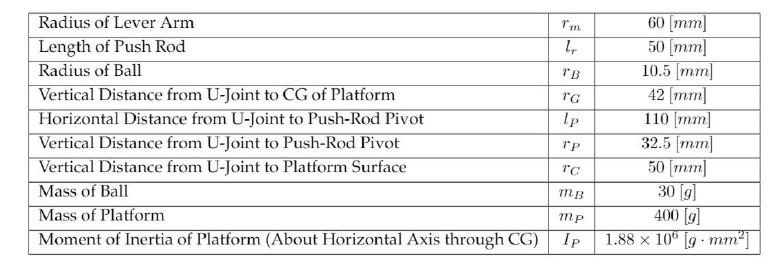

rB = .0105; %[m]
rG = .042; %[m]
rC = .050; %[m]
mB = .030; %[kg]
mP = .400; %[kg]
IP = 1.88e6*(1/1000)*(1/1000)^2; %[kg*m^2]
IB = (2/5)*mB*rB^2;%ball inertia [kg-m^2] 
g_num = 9.81; %[m/s^2]

Num_Params = [rB  rC+rB mB mP IP IB g_num rG];
Sym_Params = [r_b z_b m_b m_p I_p__xx I_b g z_p];

Substituting known numerical parameters and our assumptions into the symbolic equations of motion:

num_NL_Dcpld_SolvedEOMs_x = subs(NL_Dcpld_SolvedEOMs_x, Sym_Params, Num_Params)
num_g_x = subs(g_x, Sym_Params, Num_Params)
num_f_x = subs(f_x, Sym_Params, Num_Params)